# Plot Turbulence Empirical RSN filt (0.08-0.008)

Plot results from the empirical analysis: turbulence, information flow, information cascade and information transfer obtained in turbulence_empirical_RSN.mlx. 

TBI dataset from OpenNeuro: [https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json](https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json)

## Load results

clear all
ds1_path='/Volumes/LASA/TBI_project/TBI_openneuro/timeseries/outputs/Turbulence_28_03_2022/';
ds2_path='/Volumes/LASA/TBI_project/TBI_Helsinki/timeseries/pre_post_schaefer1000/outputs/Turbulence_16_03_2022/';
output_path='/Volumes/LASA/TBI_project/TBI_openneuro/timeseries/outputs/Turbulence_ds1patds2pat_age_TSI_30_03_2022/';
addpath '/Users/noeliamartinezmolina/Documents/GitHub/TBI_turbulence_openneuro_current_code/helper functions'
lambda={'0.27','0.24','0.21','0.18','0.15','0.12','0.09','0.06','0.03','0.01'};
cond = {'TBI_ds1','TBI_ds2'};
% dataset 1 Open Neuro
cd(ds1_path)
ds1_results = load(sprintf('turbu_all_measurements_con1.mat'));
idx_con=[1:1:12]; idx_pat=[13:1:24];
ds1_Turbu_con= ds1_results.Turbulence_global_sub(:,idx_con);
ds1_Turbu_pat= ds1_results.Turbulence_global_sub(:,idx_pat);
ds1_Turbu_RSN_con= ds1_results.TurbulenceRSN_sub(:,idx_con,:);
ds1_Turbu_RSN_pat= ds1_results.TurbulenceRSN_sub(:,idx_pat,:);
ds1_Info_flow_con = ds1_results.TransferLambda_sub(:,idx_con);
ds1_Info_flow_pat = ds1_results.TransferLambda_sub(:,idx_pat);
ds1_Info_cascade_con = ds1_results.InformationCascade_sub(:,idx_con);
ds1_Info_cascade_pat = ds1_results.InformationCascade_sub(:,idx_pat);
ds1_Info_transfer_con = ds1_results.Transfer_sub(:,idx_con);
ds1_Info_transfer_pat = ds1_results.Transfer_sub(:,idx_pat);

% dataset 2 Helsinki
cd(ds2_path)
ds2_results = load(sprintf('turbu_all_measurements_con1.mat'));
idx_ds2=sort([3 16 4 17 19 6 7 20 8 11 22]);
ds2_Turbu_pat= ds2_results.Turbulence_global_sub(:,idx_ds2);
ds2_Turbu_RSN_pat= ds2_results.TurbulenceRSN_sub(:,idx_ds2,:);
ds2_Info_flow_pat = ds2_results.TransferLambda_sub(:,idx_ds2);
ds2_Info_cascade_pat = ds2_results.InformationCascade_sub(:,idx_ds2);
ds2_Info_transfer_pat = ds2_results.Transfer_sub(:,idx_ds2);

% Merge ds1 & ds2
ds1ds2_Turbu_pat=horzcat(ds1_Turbu_pat, ds2_Turbu_pat);
ds1ds2_Turbu_RSN_pat=horzcat(ds1_Turbu_RSN_pat, ds2_Turbu_RSN_pat);
ds1ds2_Info_flow_pat=horzcat(ds1_Info_flow_pat, ds2_Info_flow_pat);
ds1ds2_Info_cascade_pat=horzcat(ds1_Info_cascade_pat, ds2_Info_cascade_pat);
ds1ds2_Info_transfer_pat=horzcat(ds1_Info_transfer_pat, ds2_Info_transfer_pat);
cd(output_path)


## Plot global Turbulence

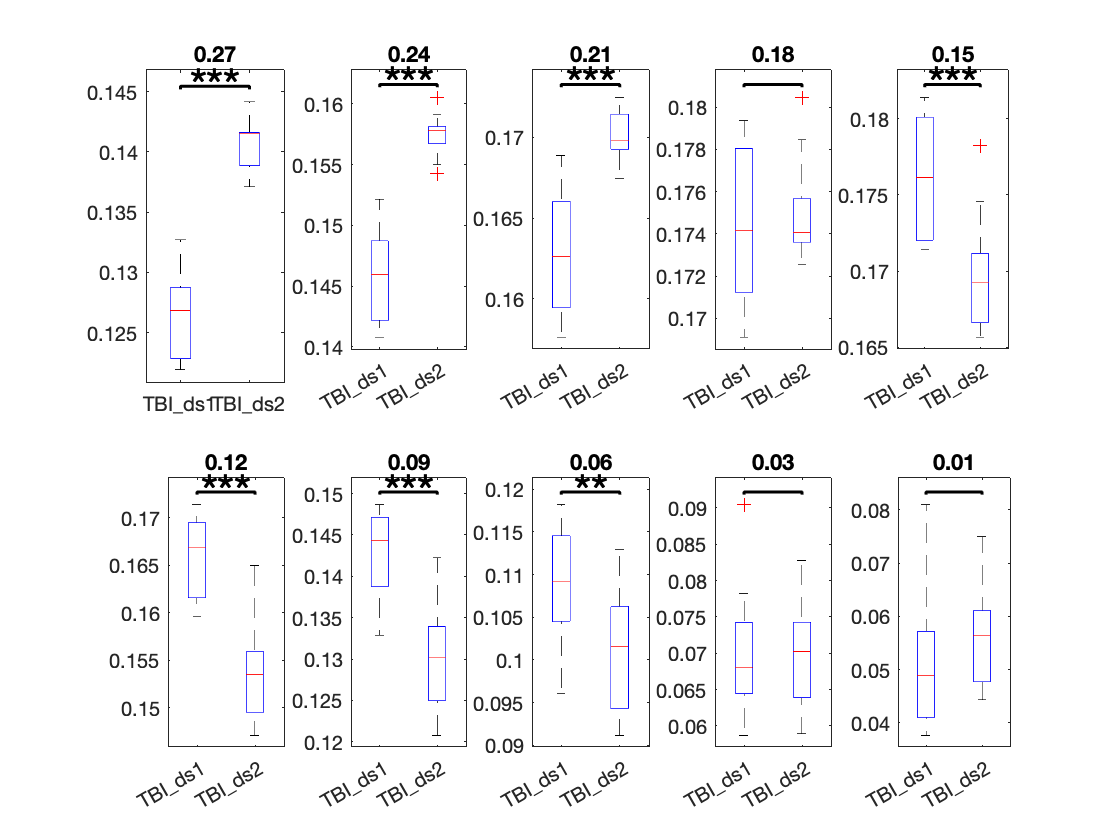

figure
for lamb=1:length(lambda)
    subplot(2,5,lamb)
    C = {ds1_Turbu_pat(lamb,:) , ds2_Turbu_pat(lamb,:)};    
    maxNumEl = max(cellfun(@numel,C));
    Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
    Cmat = cell2mat(Cpad);
    boxplot(Cmat,'Labels',cond)
    title(lambda{lamb})
    
    [~,pval] = ttest2(ds1_Turbu_pat(lamb,:),ds2_Turbu_pat(lamb,:)); % paired t Test
    p(1,lamb)=pval; clear pval
    H=sigstar({[1,2]},p(1,lamb));
end
print('Turbulence Global Open Neuro TBI AGE TSI (N=23) filt','-dpng')

close()

## Plot turbulence by RSN

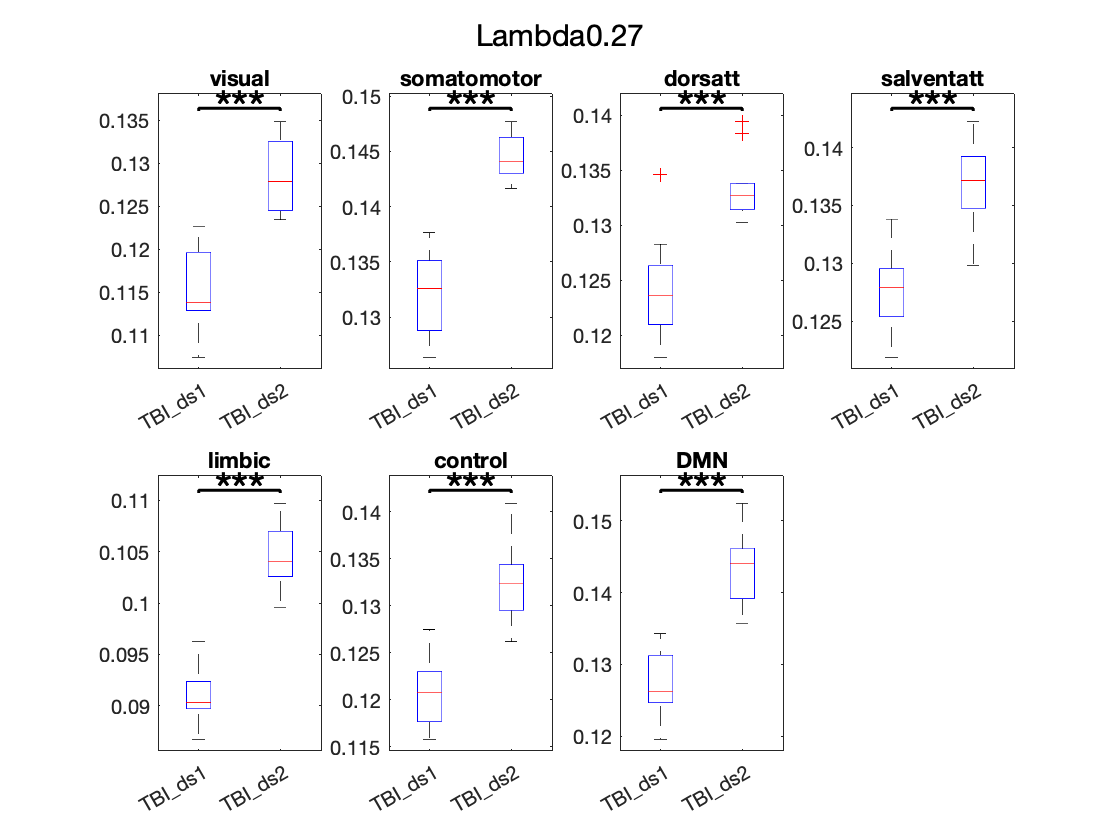

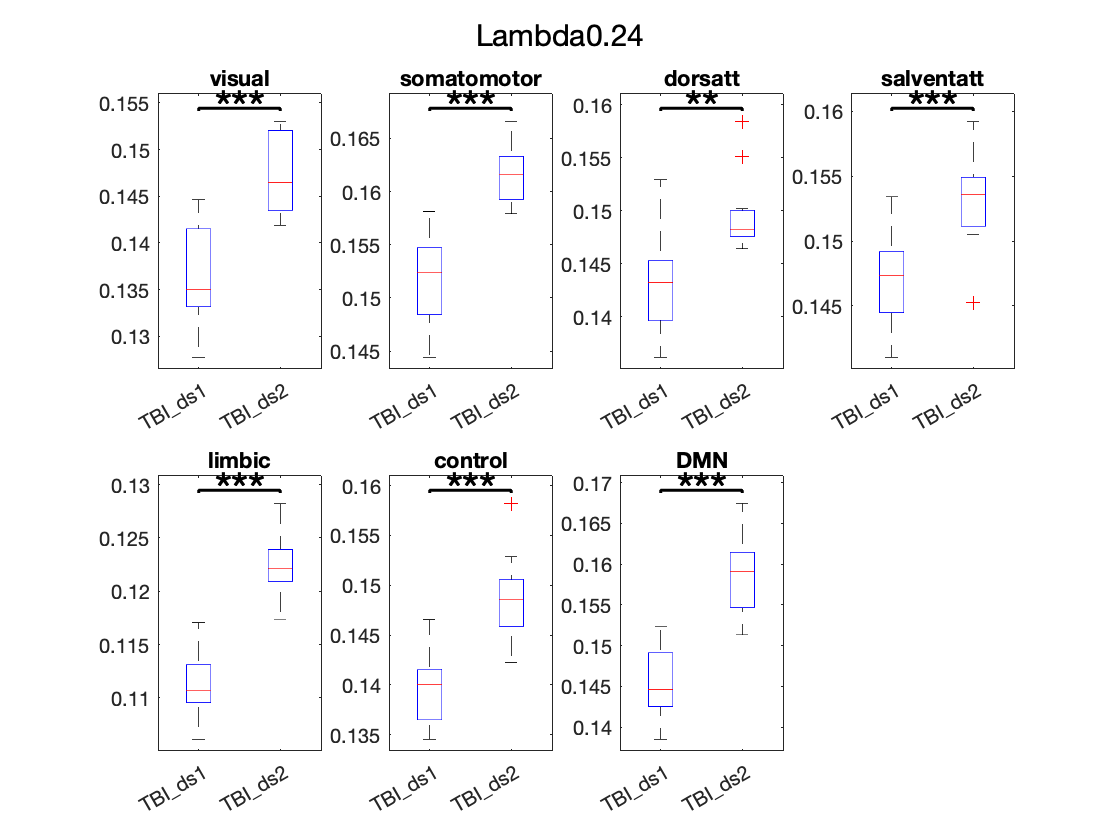

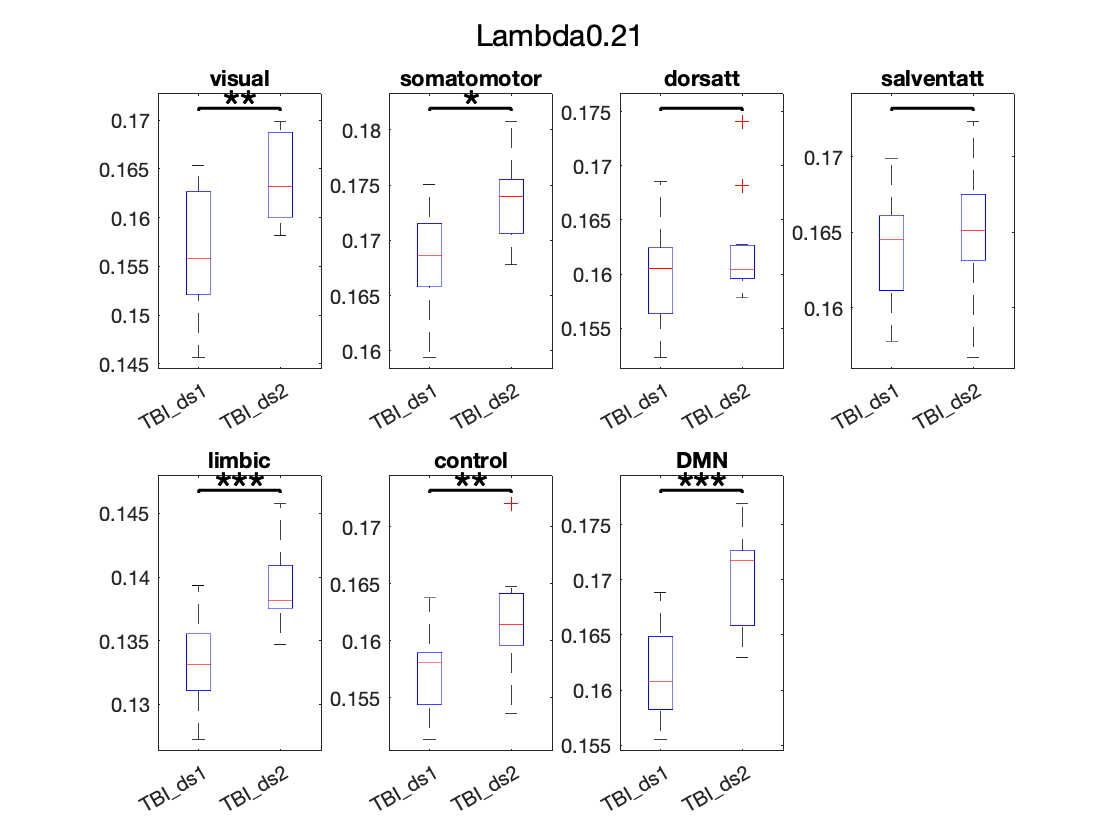

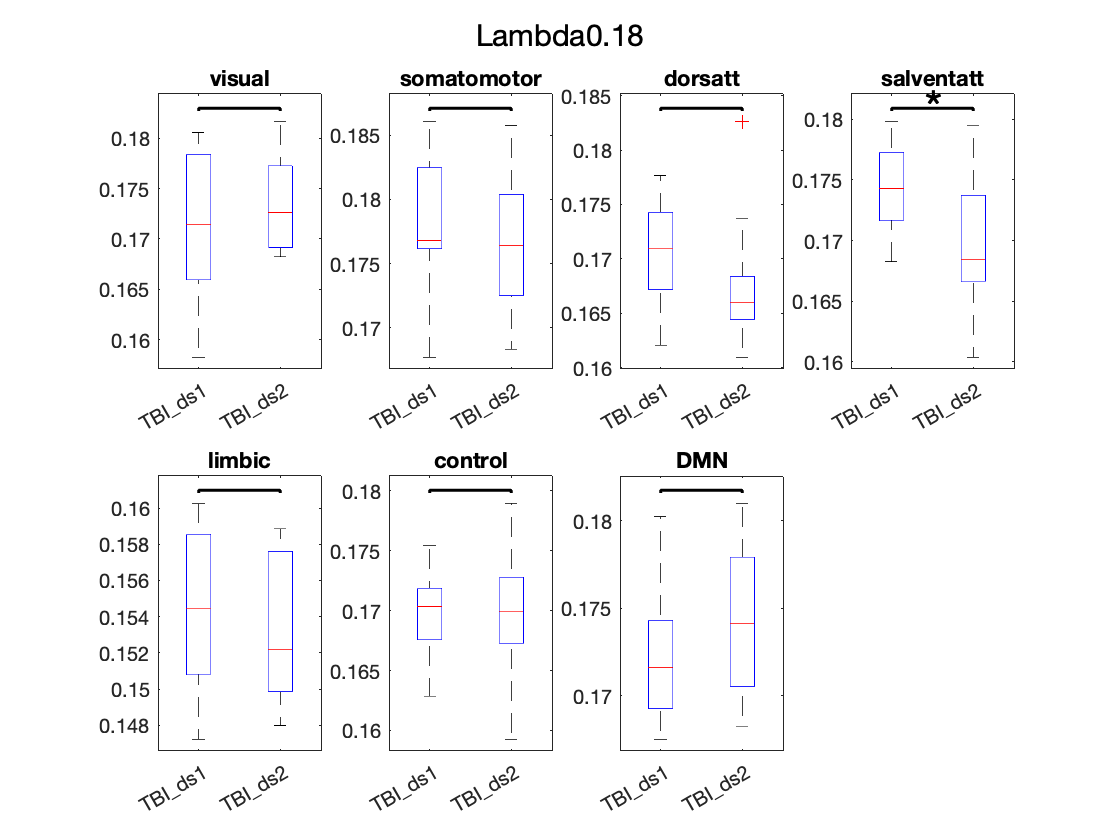

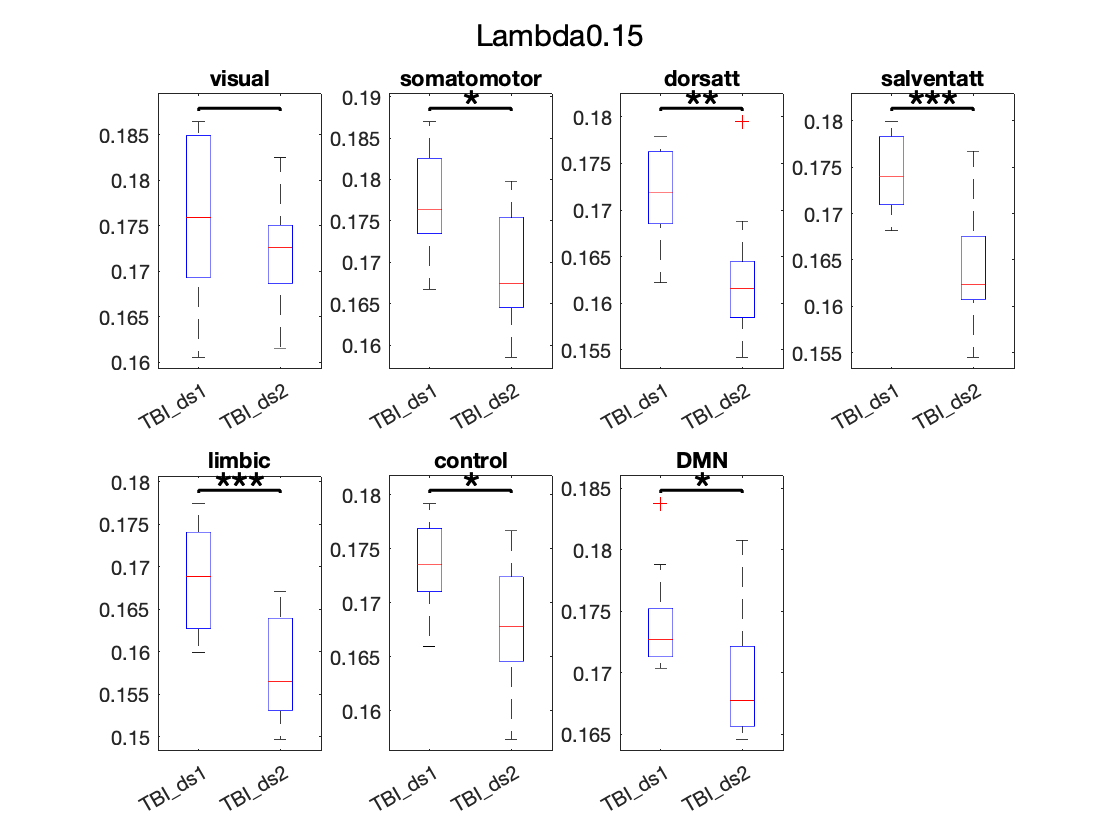

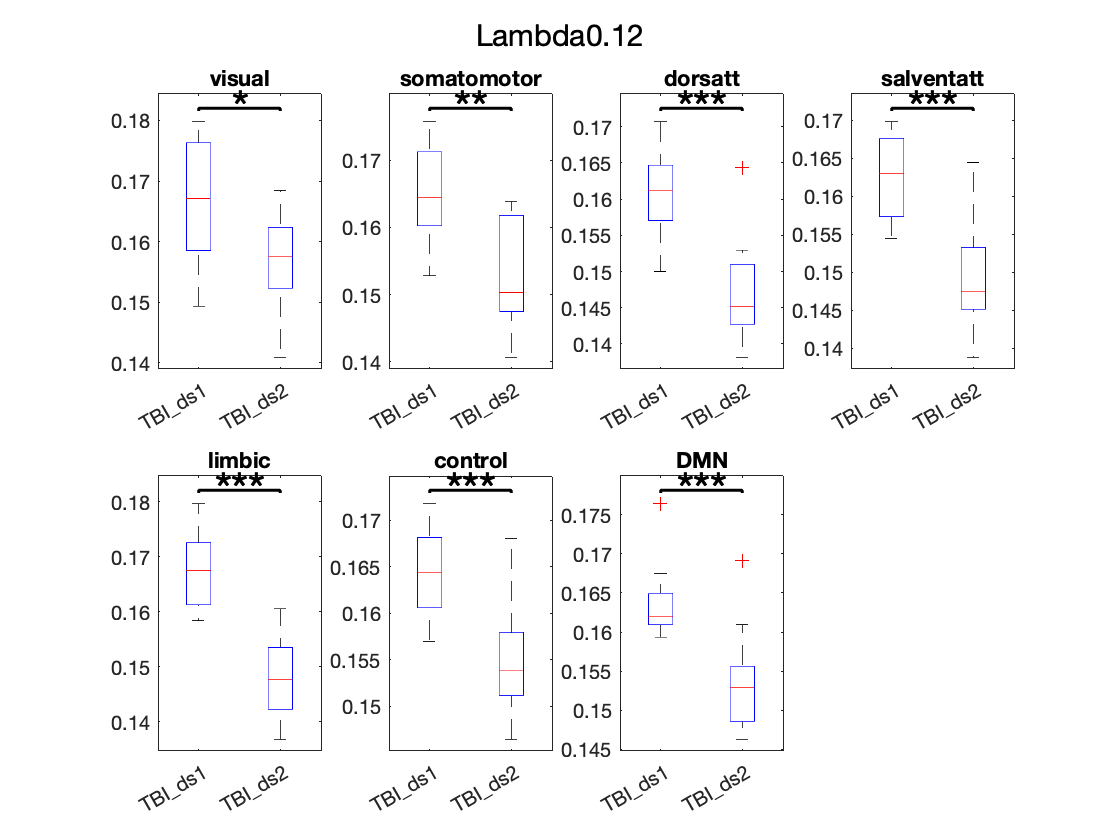

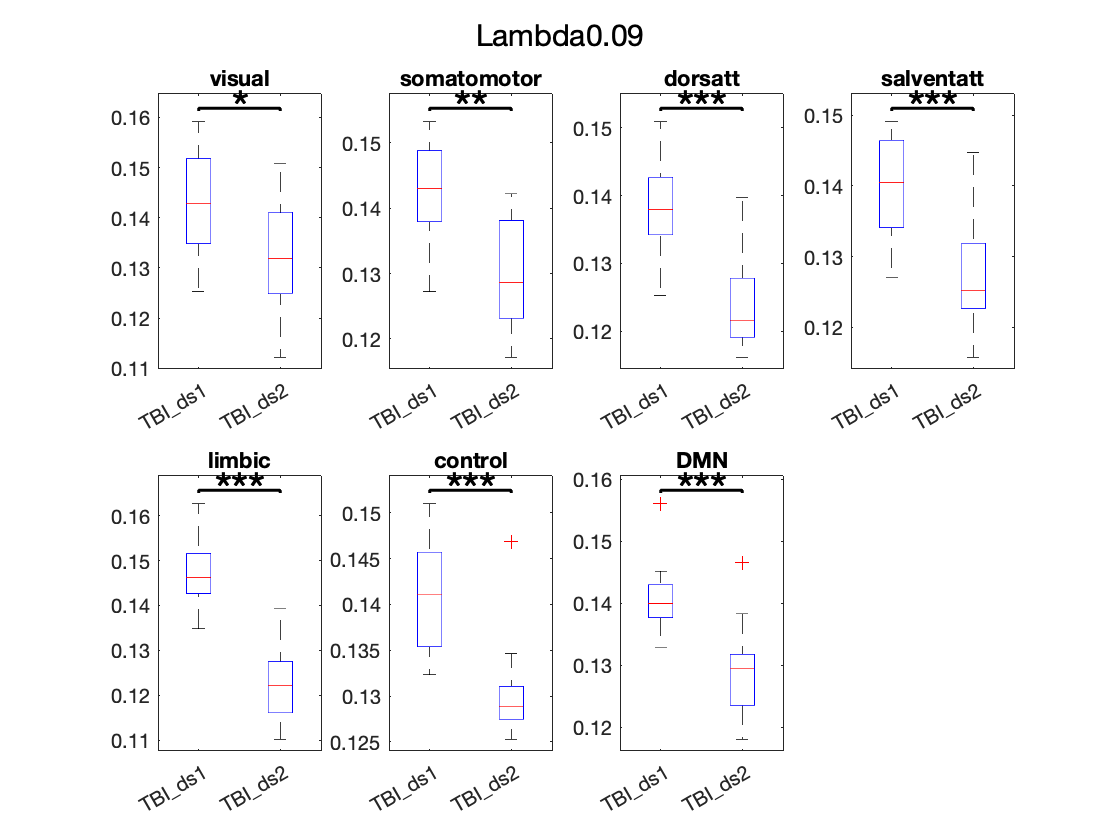

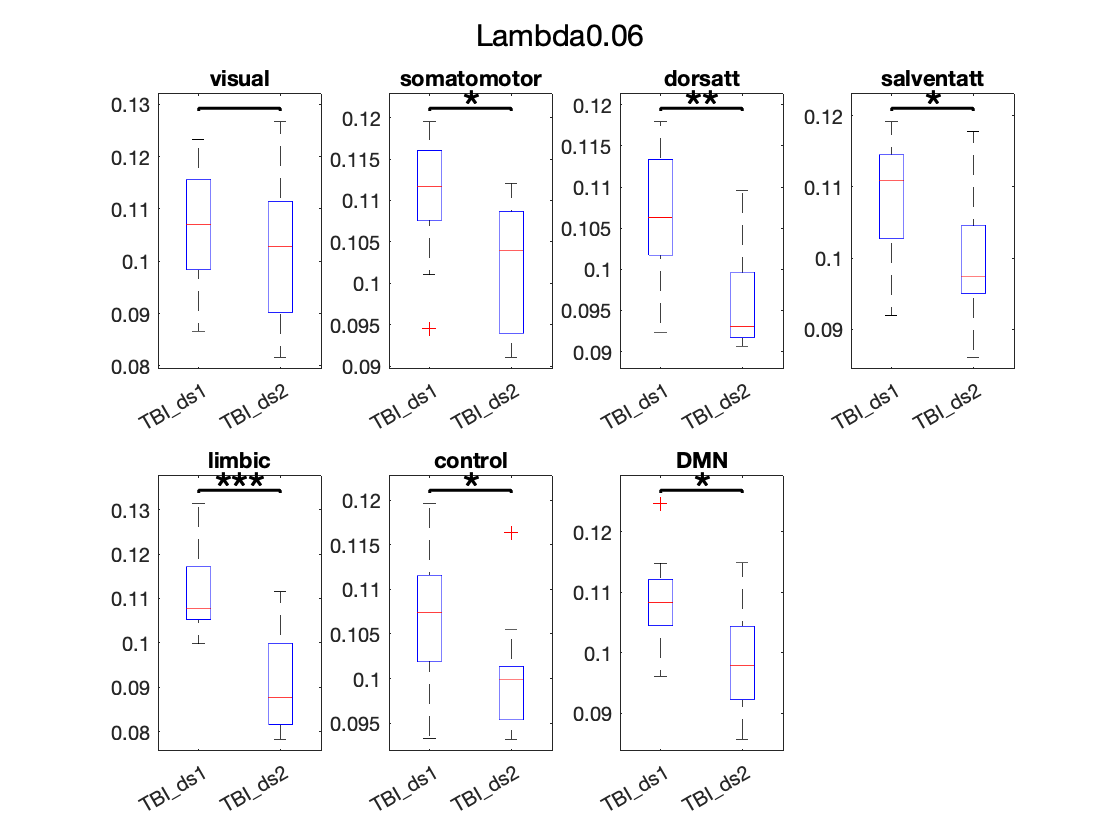

Rsns = {'visual', 'somatomotor','dorsatt','salventatt','limbic','control','DMN'};
for lamb=1:length(lambda)
    figure
    sgtitle (['Lambda' char(lambda(lamb))])
    for jj=1:7 %Loop for networks
        subplot(2,4,jj)
        C = {ds1_Turbu_RSN_pat(lamb,:,jj) , ds2_Turbu_RSN_pat(lamb,:,jj)};
        maxNumEl = max(cellfun(@numel,C));
        Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
        Cmat = cell2mat(Cpad);
        boxplot(Cmat,'Labels',cond)
        title(Rsns{jj})
        
        [~,pval] = ttest2(ds1_Turbu_RSN_pat(lamb,:,jj),ds2_Turbu_RSN_pat(lamb,:,jj)); % paired t Test
        p(1,jj)=pval; clear pval
        H=sigstar({[1,2]},p(1,jj));
    end
    print(['Turbulence RSN Open Neuro TBI AGE TSI (N=23) filt lambda' num2str(lamb)],'-dpng')
end

close()

## Plot information flow

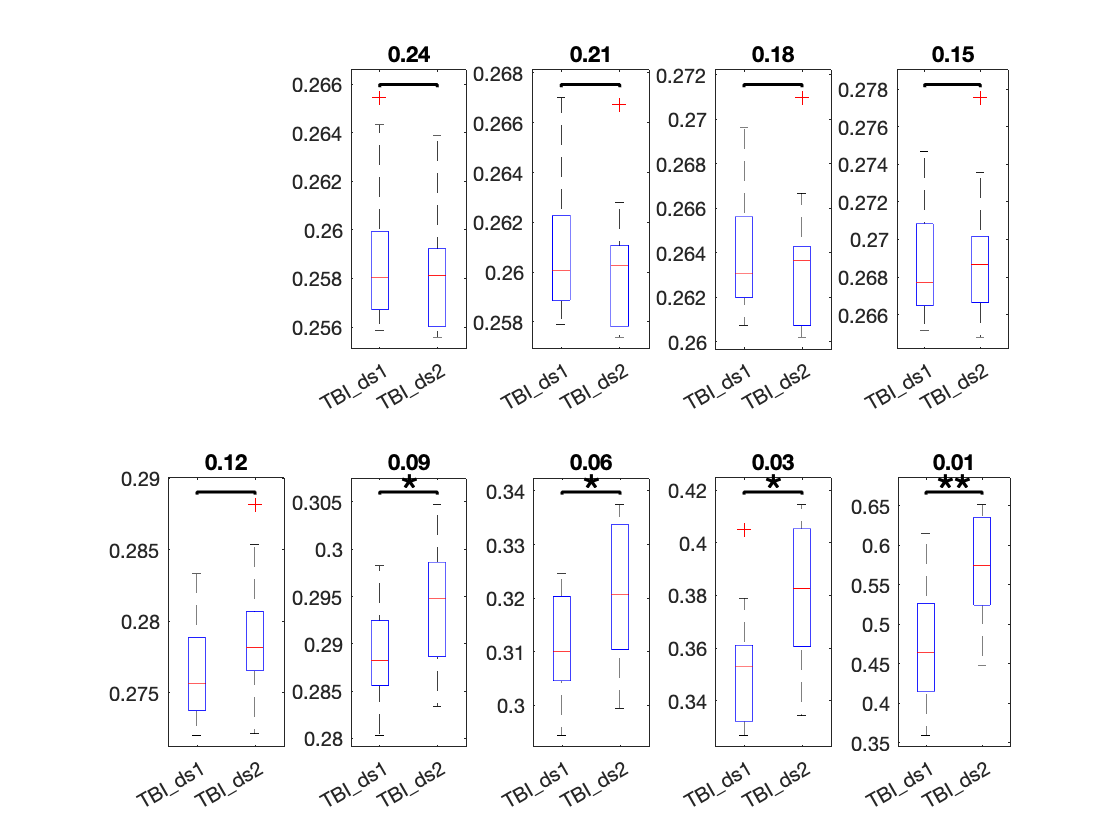

figure
for lamb=2:length(lambda)
    subplot(2,5,lamb)
    C = {ds1_Info_flow_pat(lamb,:) , ds2_Info_flow_pat(lamb,:)};    
    maxNumEl = max(cellfun(@numel,C));
    Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
    Cmat = cell2mat(Cpad);
    boxplot(Cmat,'Labels',cond)
    title(lambda{lamb})
    
    [~,pval] = ttest2(ds1_Info_flow_pat(lamb,:),ds2_Info_flow_pat(lamb,:)); % paired t Test
    p(1,lamb)=pval; clear pval
    H=sigstar({[1,2]},p(1,lamb));
end
print('Info Flow Open Neuro TBI AGE TSI(N=23) filt','-dpng')

close()

## Plot information cascade

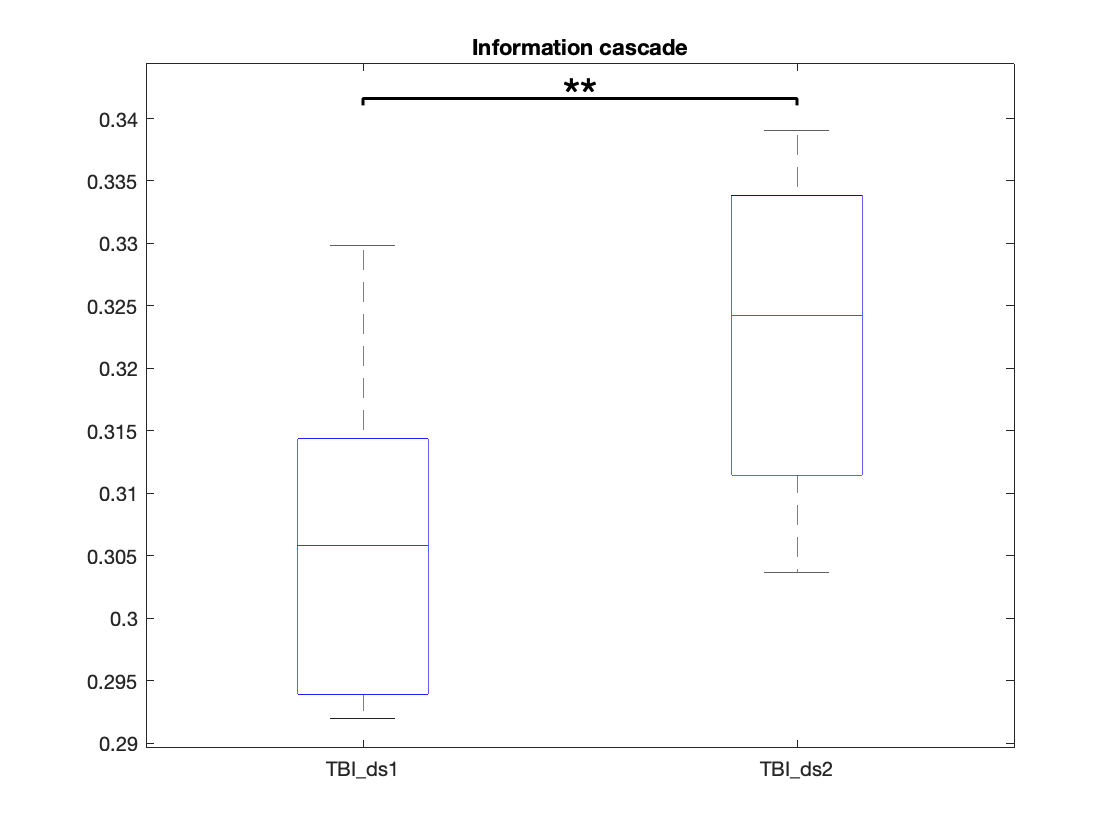

figure
C = {ds1_Info_cascade_pat, ds2_Info_cascade_pat};
maxNumEl = max(cellfun(@numel,C));
Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
Cmat = cell2mat(Cpad);
boxplot(Cmat,'Labels',cond)
title('Information cascade')

[~,pval] = ttest2(ds1_Info_cascade_pat,ds2_Info_cascade_pat); % paired t Test
H=sigstar({[1,2]},pval);
print(['Info Cascade Open Neuro TBI AGE TSI (N=23) filt lambda' num2str(lamb)],'-dpng')

close()

## Plot information transfer

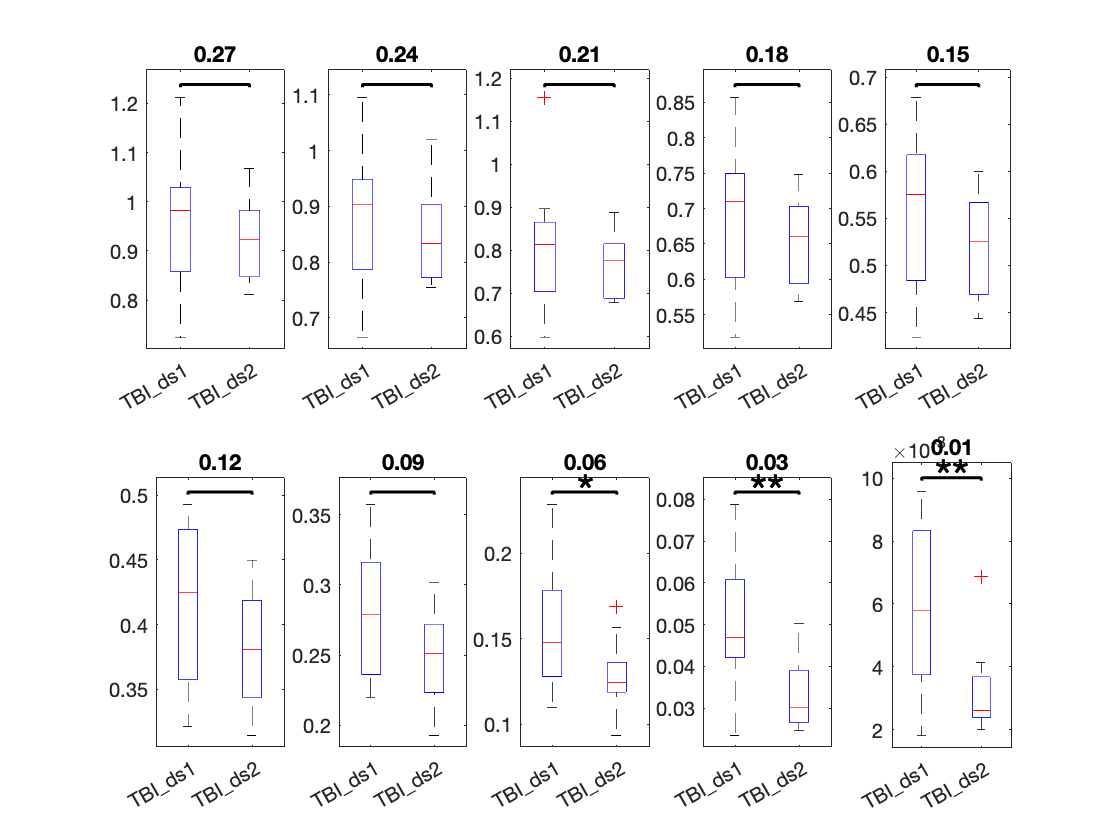

figure
for lamb=1:length(lambda)
    subplot(2,5,lamb)
    C = {ds1_Info_transfer_pat(lamb,:) , ds2_Info_transfer_pat(lamb,:)};    
    maxNumEl = max(cellfun(@numel,C));
    Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
    Cmat = cell2mat(Cpad);
    boxplot(Cmat,'Labels',cond)
    title(lambda{lamb})
    
    [~,pval] = ttest2(ds1_Info_transfer_pat(lamb,:),ds2_Info_transfer_pat(lamb,:)); % paired t Test
    p(1,lamb)=pval; clear pval
    H=sigstar({[1,2]},p(1,lamb));
end
print(['Info Transfer Open Neuro TBI AGE TSI (N=23) filt lambda' num2str(lamb)],'-dpng')

close()